% Définir le chemin d'accès racine qui contient les images
rootFolderPath = 'data';

% Définir le filtre de fichiers pour n'inclure que les images
fileFilter = '*.jpg';

% Trouver tous les fichiers correspondant au filtre dans tous les sous-dossiers
imageFiles = dir(fullfile(rootFolderPath, '**', fileFilter));

% Pour chaque fichier d'image trouvé
for i = 1:length(imageFiles)
    % Construire le chemin d'accès complet pour le fichier
    imagePath = fullfile(imageFiles(i).folder, imageFiles(i).name);
    
    % Lire l'image
    image = imread(imagePath);
    
    % Redimensionner l'image à 224x224
    image_resized = imresize(image, [224, 224]);
    
    % Sauvegarder l'image redimensionnée au même emplacement
    imwrite(image_resized, imagePath);
end


allImages = imageDatastore(fullfile('data/images_A5/'),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');
rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 460


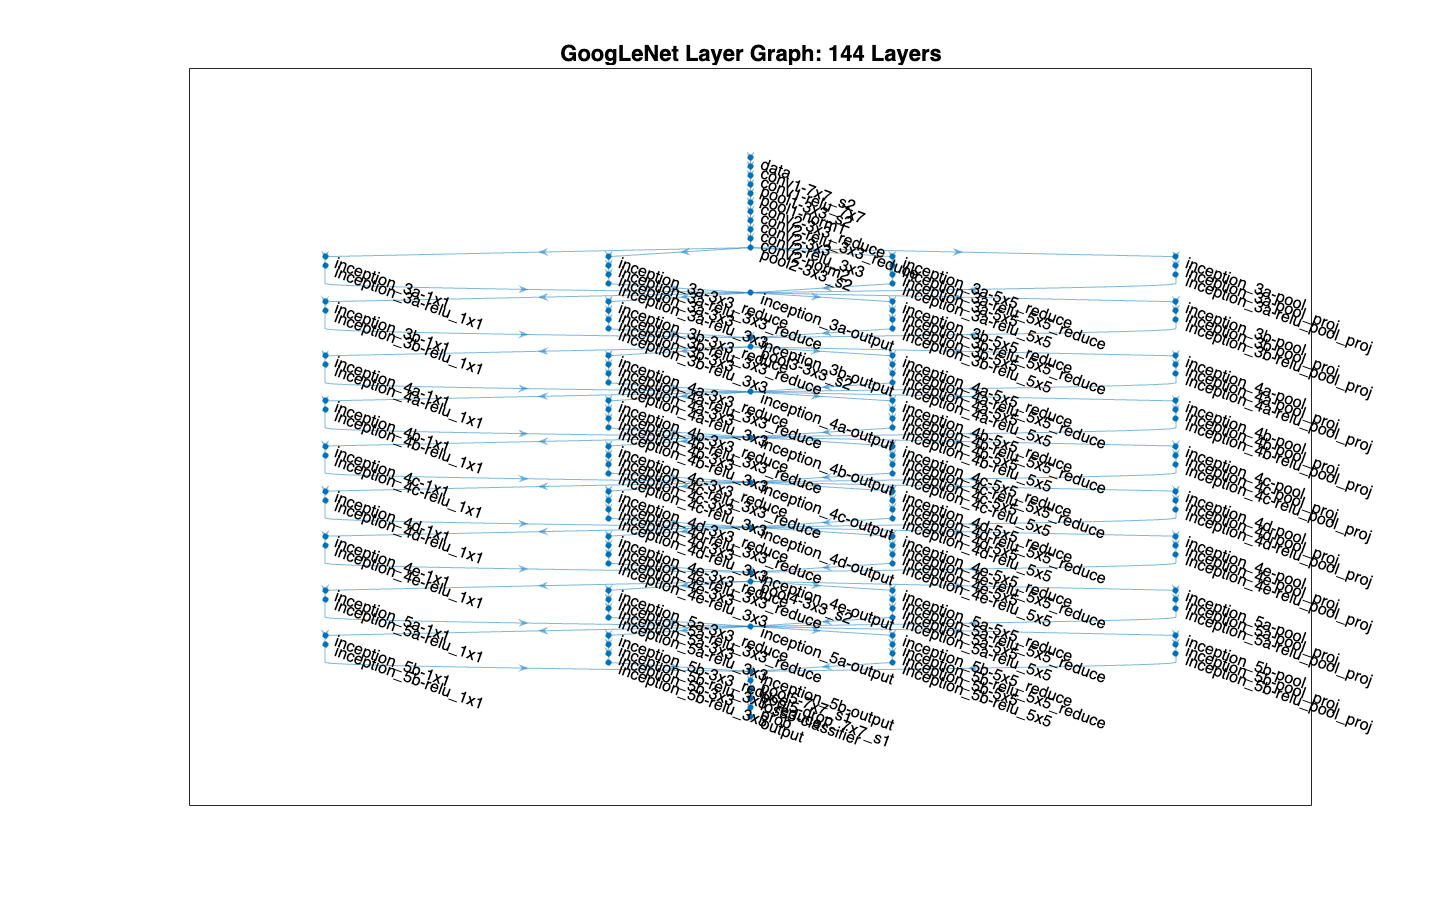

net = googlenet;
lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

net.Layers(1);

newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,['pool5-dro' ...
    'p_7x7_s1'],newDropoutLayer);
numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options = trainingOptions('sgdm',...
    'MiniBatchSize', 30,...
    'MaxEpochs', 20,...
    'InitialLearnRate', 1e-4,...
    'ValidationData', imgsValidation,...
    'ValidationFrequency', 10,...
    'Verbose', 1,...
    'ExecutionEnvironment', 'cpu',... 
    'Plots', 'training-progress'); 

trainedGN = trainNetwork(imgsTrain,lgraph,options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:29 |       33.33% |       32.76% |       1.9750 |       1.1804 |      1.0000e-04 |
|       1 |          10 |       00:02:19 |       26.67% |       33.62% |       1.6746 |       1.1163 |      1.0000e-04 |
|       2 |          20 |       00:04:05 |       30.00% |       33.62% |       1.4070 |       1.1097 |      1.0000e-04 |
|       2 |          30 |       00:05:55 |       20.00% |       35.34% |       1.2247 |       1.1128 |      1.0000

% % Load the dataset
% imds = imageDatastore('data/images_A5/', ...
%     'IncludeSubfolders',true, 'LabelSource','foldernames');

% % Split the dataset into training and validation sets
% [imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

% % Load the pretrained GoogleNet model
% net = googlenet;

% % Replace the last layer with a new fully connected layer with 3 output nodes
% % corresponding to the number of classes
% lgraph = layerGraph(net);
% numClasses = numel(categories(imdsTrain.Labels));

Unable to resolve the name 'imdsTrain.Labels'.

% newLayers = fullyConnectedLayer(numClasses, 'Name', 'new_fc');
% lgraph = replaceLayer(lgraph, 'loss3-classifier', newLayers);
% newLayers = softmaxLayer('Name', 'new_softmax');
% lgraph = replaceLayer(lgraph, 'prob', newLayers);
% newLayers = classificationLayer('Name', 'new_classoutput');
% lgraph = replaceLayer(lgraph, 'output', newLayers);

% % Set the training options
% options = trainingOptions('sgdm', ...
%     'MiniBatchSize', 32, ...
%     'MaxEpochs', 10, ...
%     'InitialLearnRate', 0.001, ...
%     'Shuffle', 'every-epoch', ...
%     'ValidationData', imdsValidation, ...
%     'ValidationFrequency', 30, ...
%     'Verbose', true, ...
%     'Plots', 'training-progress');

Unrecognized function or variable 'imdsValidation'.

% % Train the model using the specified options
% net = trainNetwork(imdsTrain, lgraph, options);

Unrecognized function or variable 'imdsTrain'.

% % Test the performance of the trained model on the validation set
% predictedLabels = classify(net, imdsValidation);
% accuracy = mean(predictedLabels == imdsValidation.Labels);
% fprintf('Accuracy on validation set: %0.2f%%\n', accuracy * 100);

Accuracy on validation set: 30.23%
